# Ball in Hemisphere

clear
% Principal parameters of ball (body C):
syms r I_s m_C real positive
I_Cg = I_s*eye(3); %any basis
% Euler angles and angular velocity components:
syms gamma(t) omega(t) [3,1] % omega = omega_CI is in basis D
% rotation matrix from inertial to body basis:
P_IC = spinmat([1,2,3],gamma.');

syms q(t) [3 1] % coordinate vector: r, phi_z (azimuth), phi_y (elevation)
P_ID = spinmat([3,2],[q2,q3]);
omega_DI = spinmat(2,-q3)*diff([0;q3;q2],t);
r_go = [q1;0;0]; %basis D
v_go = diff(r_go,t) + cross(omega_DI,r_go); % basis D

syms g real positive

% LMB:
syms F_p [3,1] real % basis D
F_g = [0;0;-m_C*g]; % basis I
F_C = simplify( F_p + P_ID.'*F_g == m_C*(diff(v_go,t)+cross(omega_DI,v_go)) );

%AMB:
r_pg = [r;0;0]; %basis D
M_Cg = cross(r_pg,F_p) == diff(I_Cg*omega,t) + cross(omega_DI,I_Cg*omega);

% no slip constraint: v_po = v_pg + v_go = 0
v_po = cross(omega,r_pg) + v_go == 0;
a_po = simplify(diff(v_po,t));


syms omega_dot_ q_dot_ q_ddot_ [3,1] real
eqns = subs([F_C;M_Cg;a_po],[diff(q,t,t);diff(omega,t)], [q_ddot_;omega_dot_]);
eqns = subs(eqns,diff(q,t),q_dot_);
eqns = subs(eqns,[q;gamma;omega],[sym('q',[3,1]);sym('gamma',[3,1]);sym('omega',[3,1])]);

[A,f] = equationsToMatrix(eqns,[q_ddot_;omega_dot_;F_p]);

vars = [sym('q',[3,1]);sym('gamma',[3,1]);q_dot_;sym('omega',[3,1])];
%clear up some RAM
clearvars -except A f vars

## Substitute in Values:

% dimensional parameters:
R = 1;
r = 0.3;
m_C = 3;
g = 9.8;

%initial conditions
q0 = [R-r; 0; 0.5]; % r; phi_z; phi_y
omega0 = [0;1;3];

%simulation duration:
tf = 5;

%don't adjust these:
gamma0= [0;0;0];
v_go0 = -cross(omega0,[r;0;0]);
q_dot0 = [0;1/(q0(1)*cos(q0(3)))*v_go0(2);-1/(q0(1))*v_go0(3)];

I_s = (2/5)*m_C*r^2;

## Integrate:

hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{vars});

% % gamma_dot in terms of gamma and omega:
% hw = @(g,w)[sec(g(2)),0,0;0,1,0;-tan(g(2)),0,1]*spinmat([2,1],-[g(2),g(1)])*w;

% z = [q;gamma;q_dot;omega]
function z_dot = EOM(~,z,hA,hf)
gamma_dot = [1,0,-tan(z(5));0,1,0;0,0,sec(z(5))]*spinmat([1,3,2],[-z(4),z(2),z(3)])*z(10:12);
u = hA(z)\hf(z);
z_dot = [z(7:9); %q_dot
         gamma_dot;
         u(1:6)]; % [q_ddot;omega_dot]
end

[t,z] = ode45(@(t,z)EOM(t,z,hA,hf), linspace(0,tf,30*tf),[q0;gamma0;q_dot0;omega0]);
z=z';

## Animate:

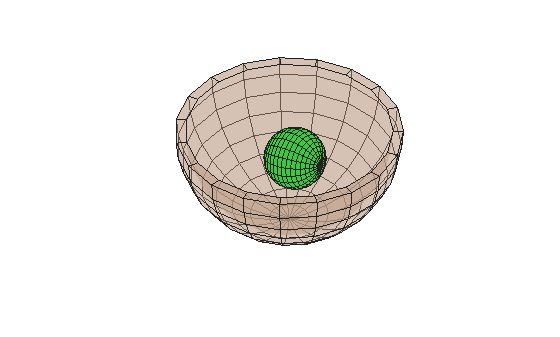

P_ID = @(i) spinmat([3,2],z([2,3],i)');
r_go = @(i) P_ID(i)*[z(1,i);0;0]; % basis I

figure(1)
clf
hold on
view([0 40])
% make shell:
shell = hgtransform;
buildShell(shell,R,1.1*R,pi,[.75,.63,.54],0.4)
%make ball:
ball = hgtransform;
[a,b,c]=sphere;
surf(r*a,r*b,r*c,'FaceColor',[.24,.79,.24],'Parent',ball)
axis equal off
% axis([-1,1,-1,1,0,1.5]*1.3*R_Bo)
axis manual
for i = 1:length(t)
    set(ball, 'Matrix',[spinmat([1,2,3],z([4,5,6],i)'),r_go(i);[0,0,0,1]])
    drawnow
end

## Check Everything makes sense:

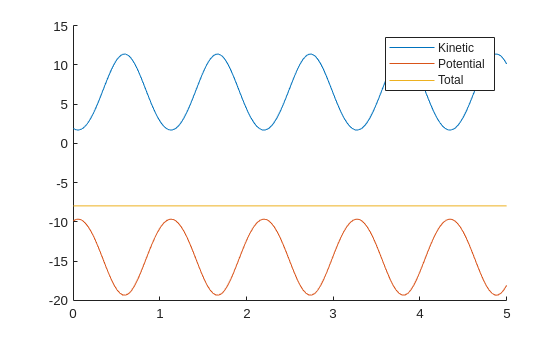

I_Cg = I_s*eye(3); %any basis
v_go = @(i) P_ID(i)*([z(7,i);0;0] + cross([-z(8,i)*sin(z(3,i));z(9,i);z(8,i)*cos(z(3,i))],[z(1,i);0;0]));
T_C = arrayfun(@(i) (1/2)*z(10:12,i)'*I_Cg*z(10:12,i) + (1/2)*m_C*v_go(i)'*v_go(i),1:length(t));
V_C = arrayfun(@(i) [0,0,m_C*g]*r_go(i),1:length(t));

figure(2)
clf
hold on
plot(t,T_C,'DisplayName','Kinetic')
plot(t,V_C,'DisplayName','Potential')
plot(t,T_C+V_C,'DisplayName','Total')
legend

## Helper Functions:

function buildShell(hg, R_in,R_out,angle,colr,alpha)
theta = linspace(pi-angle/2,pi,round(10*angle/pi))'; phi = linspace(0,2*pi,20);
x = cos(phi).*sin(theta); y = sin(phi).*sin(theta); z = cos(theta)*ones(size(phi));
surf(R_out*x,R_out*y,R_out*z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
if angle<2*pi && R_in>0
    surf(R_in*x, R_in*y, R_in*z,'FaceColor',colr,'EdgeColor','none','FaceAlpha',alpha,'Parent',hg)
    r = [R_in;R_out].*ones(size(phi));
    theta = pi-angle/2;
    x = r.*cos(phi)*sin(theta); y = r.*sin(phi)*sin(theta); z = r.*cos(theta);
    surf(x,y,z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
end
end